# Getting Started with `batch`

You can use `batch` jobs to offload the execution of long-running computations in the background and carry out other tasks while the batch job is processing. `batch` does not block MATLAB and you can continue working while computations take place. When you submit batch jobs to another computer or cluster, you can even close MATLAB on the client, and retrieve results later.

In this exercise, you will submit batch jobs from MATLAB to your local machine. The workers will run on the same machine as the client, but the same workflow can be used to submit jobs to a remote compute cluster or the cloud, freeing up your local resources.

## Run a `batch` job to offload a serial computation

`batch` runs your code on a local worker or a cluster worker, but does not require a parallel pool. Close a parallel pool, if one is open.

delete(gcp('nocreate'))

Use the [batch](https://www.mathworks.com/help/releases/R2018b/distcomp/batch.html?searchHighlight=batch&s_tid=doc_srchtitle) command to offload the function `ex_serial` to one MATLAB worker session that runs in the background, while you can continue using MATLAB as computations take place. 

The function performs `N` trials of computing the largest eigenvalue for an `M-by-M` random matrix and runs serially.

numOutputs = 1;
input1 = 50;
input2 = 10000;
job1 = batch(@ex_serial,numOutputs,{input1,input2});

## Job Monitor

`batch` does not block MATLAB and you can continue working while computations take place. If you want to block MATLAB until the job finishes, use the `wait` function on the job object.

You can determine the status of your job using the Job Monitor. The Job Monitor displays all the jobs that exist for the cluster specified in the selected profile. Open the Job Monitor from the **Home** tab in the **Environment** section, by selecting **Parallel** > **Monitor Jobs**.

What is the state of your job?

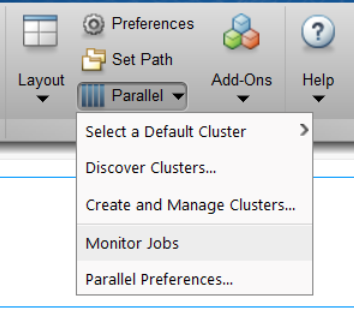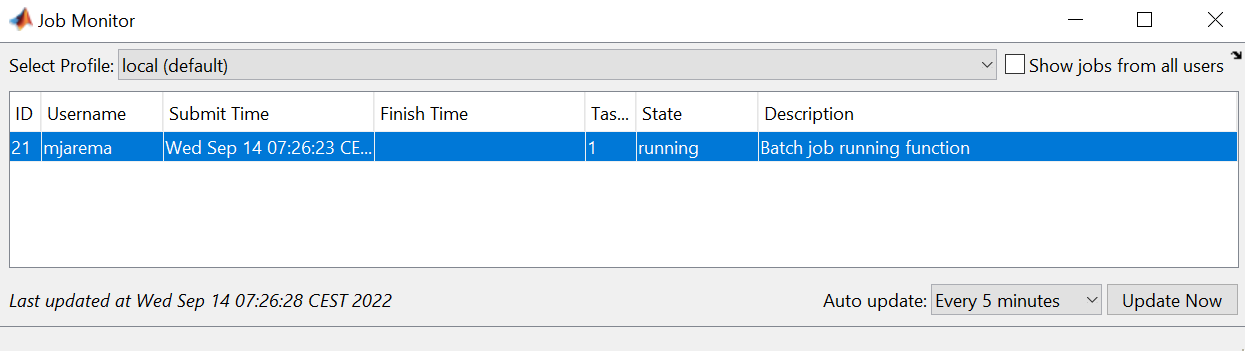

### Get the job results

Using the Job Monitor you can manage the listed jobs for your cluster. Right-click on any job in the list, and select any of the following options from the context menu. The available options depend on the type of job.

- **Cancel** — Stops a running job and changes its state to `'finished'`. If the job is pending or queued, the state changes to `'finished'` without its ever running. This is the same as the command-line [`cancel`](https://www.mathworks.com/help/parallel-computing/parallel.task.cancel.html) function for the job.

- **Delete** — Deletes the job data and removes the job from the queue. This is the same as the command-line [`delete`](https://www.mathworks.com/help/parallel-computing/parallel.job.delete.html) function for the job. Also closes and deletes an interactive pool job.

- **Show Details** — This displays detailed information about the job in the Command Window.

- **Show Errors** — This displays all the tasks that generated an error in that job, with their error properties.

- **Fetch Outputs** — This collects all the task output arguments from the job into the client workspace.

When the job completes, retrieve the results interactively.

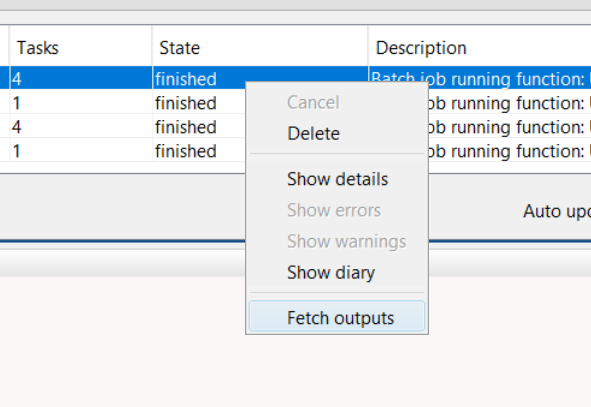

When you have loaded all the required variables, delete the job object programmatically to clean up its data and avoid consuming resources unnecessarily. 

%TODO delete job programmatically
clear job1

## Offload parallel computation

You can combine the abilities to offload a job and run a loop in a parallel pool. Use the [batch](https://www.mathworks.com/help/releases/R2018b/distcomp/batch.html?searchHighlight=batch&s_tid=doc_srchtitle) command to offload the function `ex_parallel`. 

The function performs `N` trials of computing the largest eigenvalue for an `M-by-M` random matrix and runs in parallel. Indicate in the `batch` command that a parallel pool should be used, where `numWorkers` are to evaluate the loop iterations:

numOutputs = 1;
input1 = 50;
input2 = 10000;
numWorkers = 2;
job2 = batch(@ex_parallel,numOutputs,{input1,input2},'Pool',numWorkers);

 How many workers are used and how many MATLAB sessions are involved?

*Hint*: The total number of workers will be one more than the size of the pool. Why?

Besides the `numWorkers` used to evaluate the loop iterations, an additional worker runs the serial code. Thus, `numWorkers`+1 workers are used and there are `numWorkers`+2 MATLAB sessions involved:

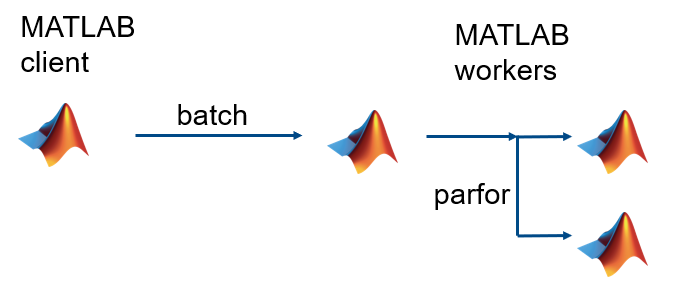

### Query the state of `job2`

Query the state of the parallel job programatically.

job2.State

ans = 'running'

### Wait for `job2` to finish

Wait for the parallel job to complete programmatically.

*Hint*: Take a look at the [wait](https://www.mathworks.com/help/releases/R2019a/parallel-computing/wait.html) method.

%TODO Fill in this line to wait for the parallel job to complete programmatically.
job2.State

### Get results back to client

Retrieve the parallel job results programmatically.

%TODO Fill in the next line to retrieve the parallel job results programmatically in a variable results2.

ans = 'finished'

results2;

### Clean up

Delete `job2` interactively from the Job Monitor.